# Run Param_lab3_real.mlx

## Run General parameter

Tw_awu = ts_5/5;
Kw_awu = 1/Tw_awu;

## Set step amplitude 50 deg

step_amplitude = 50;

# Simulate value with no antiwindup filter step 50 [deg] (lab3_windup_sim_real) o box

## Salva dati no antiwind up 50 deg

t = ScopeData1.time;
tetha = ScopeData1.signals(1).values;  
ref = ScopeData1.signals(2).values;
error = ScopeData1.signals(3).values;
command_u =  ScopeData1.signals(4).values;

save("windup_data_lab3_50_real_lab3.mat",'t','tetha','ref','error','command_u');


# Simulate value with antiwindup filter step 50 [deg] (lab3_antiwindup_sim_real) o box

## Salva dati antiwind up 50 deg

t1 = ScopeData1.time;
tetha1 = ScopeData1.signals(1).values;  
ref1 = ScopeData1.signals(2).values;
error1 = ScopeData1.signals(3).values;
command_u1 =  ScopeData1.signals(4).values;

save("antiwindup_data_lab3_50_real_lab3.mat",'t1','tetha1','ref1','error1','command_u1');

## Set step amplitude120 deg

step_amplitude = 120;

# Simulate value with no antiwindup filter step 120 [deg] (lab3_windup_sim_real) o box

## Salva dati no antiwind up 120 deg


t2 = ScopeData1.time;
tetha2 = ScopeData1.signals(1).values;  
ref2 = ScopeData1.signals(2).values;
error2 = ScopeData1.signals(3).values;
command_u2 =  ScopeData1.signals(4).values;

save("windup_data_lab3_120_real_lab3.mat",'t2','tetha2','ref2','error2','command_u2');


# Simulate value with antiwindup filter step 120 [deg] (lab3_antiwindup_sim_real) o box

## Salva dati with antiwind up 120 deg


t3 = ScopeData1.time;
tetha3 = ScopeData1.signals(1).values;  
ref3 = ScopeData1.signals(2).values;
error3 = ScopeData1.signals(3).values;
command_u3 =  ScopeData1.signals(4).values;

save("antiwindup_data_lab3_120_real_lab3.mat",'t1','tetha1','ref1','error1','command_u1');


## Stampa grafici

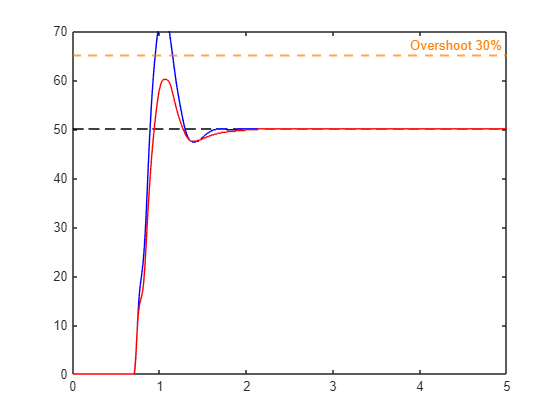


% grafico step 50 deg

load("windup_data_lab3_50_real_lab3.mat");
load("antiwindup_data_lab3_50_real_lab3.mat");
figure;
plot(t,ref,'k--');
yline(65, '--', 'Color', '[1, 0.5, 0]', 'LineWidth', 1.5, 'Label', 'Overshoot 30%');
hold on 
plot(t,tetha,'b');
plot(t1,tetha1,'r');
axis([0 5 0 70])
hold off

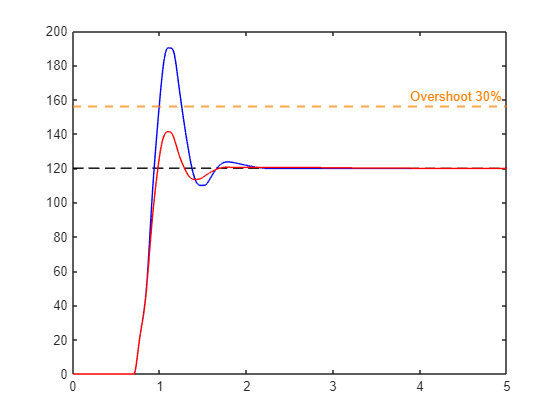


load("windup_data_lab3_120_real_lab3.mat");
load("antiwindup_data_lab3_120_real_lab3.mat");

% grafico step 120 deg

figure;
plot(t2,ref2,'k--');

hold on 
yline(156, '--', 'Color', '[1, 0.5, 0]', 'LineWidth', 1.5, 'Label', 'Overshoot 30%');
plot(t2,tetha2,'b');
plot(t3,tetha3,'r');
axis([0 5 0 200])
hold off

#### Step response parameters

% Calcolo dei dati mantenendo i tuoi nomi originali
step_50_wind_up = stepinfo(tetha, t, 50, 'SettlingTimeThreshold', 0.05);
step_50_anti_wind_up = stepinfo(tetha1, t1, 50, 'SettlingTimeThreshold', 0.05);
step_120_wind_up = stepinfo(tetha2, t2, 120, 'SettlingTimeThreshold', 0.05);
step_120_anti_wind_up = stepinfo(tetha3, t3, 120, 'SettlingTimeThreshold', 0.05);

% Raccolta dei risultati in un array di strutture
results = [step_50_wind_up; step_50_anti_wind_up; step_120_wind_up; step_120_anti_wind_up];

% Conversione in tabella
T = struct2table(results);

% Aggiunta dei nomi delle righe per chiarezza
T.Properties.RowNames = {
    'step_50_wind_up', ...
    'step_50_anti_wind_up', ...
    'step_120_wind_up', ...
    'step_120_anti_wind_up'
};

% Visualizzazione della tabella

disp(T(:, {'RiseTime', 'SettlingTime', 'Overshoot'}))

                             RiseTime    SettlingTime    Overshoot
                             ________    ____________    _________

    step_50_wind_up           0.149          0.915         46.88  
    step_50_anti_wind_up      0.192        0.58699         19.52  
    step_120_wind_up          0.177        0.98299          57.8  
    step_120_anti_wind_up     0.217        0.86899          18.5  

